# ** Data processing, No. 1 borehole in Jintan City**

close all
clc
clear
warning off
format long

## Data format (important!), Sort by filed test project

- nzsensing DTS_+Tstart+_+Tend+.mat or Ultima DTS_+Tstart+_+Tend+.mat; Save it as basic data

- Test information = Info.mat

- Data in borehole and the certain time = Test+number1+Process+number2.timeseconds/temperarure/anti-temperature/depth/anti-depth.mat; number1 = the number of test in one field project; number2 = 1/2, 1 = time parting, and 2 = depth parting

- Thermal response test in borehole and the certain time = Heat + the contents in (3)

- Natural temperarture in borehole and the certain time = Natural + the contents in (3)

- Data tranform in Natural temperature in our database (jintan.mat). jintan.bore+borehole number+.depth+yyyymmdd = NaturalProcess2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2);

- Thermal conducivity results. TC.begin_t+number*, TC.finish_t+number*, number* is the serial number of thermal response test; TC.value+number*, number* is the serial number of thermal response test

- Save above data (every field project). jintan.bore+borehole number+.depth+yyyymmdd = Natural+number1+Process+number2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2)

- Data tranform in Thermal Conductivity in our database (jintan.mat). jintan.bore+borehole number+.thermalConductivity+yyyymmdd= TC.value

## Fileld Project-202109

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS1.startTime=startTime;
DTS1.RT=RT;
DTS1.RTP1=RTP1;
DTS1.RTP2=RTP2;
DTS1.LAF=LAF;
DTS1.ST=ST;
DTS1.AST=AST;
DTS1.REV_ST=REV_ST;
DTS1.REV_AST=REV_AST;
DTS1.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS1_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS1');

clearvars -except DTS1;

#### Additional test

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS2.startTime=startTime;
DTS2.RT=RT;
DTS2.RTP1=RTP1;
DTS2.RTP2=RTP2;
DTS2.LAF=LAF;
DTS2.ST=ST;
DTS2.AST=AST;
DTS2.REV_ST=REV_ST;
DTS2.REV_AST=REV_AST;
DTS2.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS2_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS2');

clearvars -except DTS1 DTS2;

#### 2 Time information

Info1.start_test = '2021/09/22  13:55:00'; % apply the test
Info1.start_heating = '2021/09/22  15:45:00'; % begain heating
Info1.end_heating = '2021/09/22  16:03:00'; % end of heating
Info1.end_test = '2021/09/22  17:15:00'; % finish the test
Info1.heating_power = 15; % heating power
clearvars -except Info1 DTS1 DTS2;

#### Additional test

Info2.start_test = '2021/09/26  09:50:00'; % apply the test
Info2.start_heating = '2021/09/26  10:00:00'; % begain heating
Info2.end_heating = '2021/09/26  16:00:00'; % end of heating
Info2.end_test = '2021/09/26  16:55:00'; % finish the test
Info2.heating_power = 15; % heating power
clearvars -except Info1 Info2 DTS1 DTS2;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS1.startTime)
    t_processing = DTS1.startTime(1,i);
    if t_processing>=Info1.start_test && t_processing<=Info1.end_test
        p = p+1;
        date(1,p) = DTS1.startTime(1,i);
        temperature_processing(:,p) = DTS1.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info1.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info1 DTS1 Info2 DTS2;


p = 0;
for i = 1:length(DTS2.startTime)
    t_processing = DTS2.startTime(1,i);
    if t_processing>=Info2.start_test && t_processing<=Info2.end_test
        p = p+1;
        date(1,p) = DTS2.startTime(1,i);
        temperature_processing(:,p) = DTS2.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info2.start_test);
    end
end

Test2Process1.timeseconds = time_seconds;
Test2Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Test2Process1 Info1 DTS1 Info2 DTS2;


p = 0;
for i = 1:length(DTS1.startTime)
    t_processing = DTS1.startTime(1,i);
    if t_processing>=Info1.start_heating && t_processing<=Info1.end_heating
        p = p+1;
        date(1,p) = DTS1.startTime(1,i);
        temperature_processing(:,p) = DTS1.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info1.start_heating);
    end
end

Heat1Process1.timeseconds = time_seconds;
Heat1Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 Test1Process1 Test2Process1 Info1 DTS1 Info2 DTS2;


p = 0;
for i = 1:length(DTS2.startTime)
    t_processing = DTS2.startTime(1,i);
    if t_processing>=Info2.start_heating && t_processing<=Info2.end_heating
        p = p+1;
        date(1,p) = DTS2.startTime(1,i);
        temperature_processing(:,p) = DTS2.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info2.start_heating);
    end
end

Heat2Process1.timeseconds = time_seconds;
Heat2Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 Heat2Process1 Test1Process1 Test2Process1 Info1 DTS1 Info2 DTS2;


p = 0;
for i = 1:length(DTS1.startTime)
    t_processing = DTS1.startTime(1,i);
    if t_processing>=Info1.start_test && t_processing<=Info1.start_heating
        p = p+1;
        date(1,p) = DTS1.startTime(1,i);
        temperature_processing(:,p) = DTS1.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info1.start_test);
    end
end

Natural1Process1.timeseconds = time_seconds;
Natural1Process1.temperature = temperature_processing;
clearvars -except Natural1Process1 Heat1Process1 Heat2Process1 Test1Process1 Test2Process1 Info1 DTS1 Info2 DTS2;


p = 0;
for i = 1:length(DTS2.startTime)
    t_processing = DTS2.startTime(1,i);
    if t_processing>=Info2.start_test && t_processing<=Info2.start_heating
        p = p+1;
        date(1,p) = DTS2.startTime(1,i);
        temperature_processing(:,p) = DTS2.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info2.start_test);
    end
end

Natural2Process1.timeseconds = time_seconds;
Natural2Process1.temperature = temperature_processing;
clearvars -except Natural1Process1 Natural2Process1 Heat1Process1 Heat2Process1 Test1Process1 Test2Process1 Info1 DTS1 Info2 DTS2;

#### 4 Check the length

figure(1)
plot(DTS1.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS1.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');
% 202209Borehole [74.823,174.469,274.37]

#### Additional test

figure(2)
plot(DTS2.LAF,Test2Process1.temperature(:,1))
hold on
plot(DTS2.LAF,Test2Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');
% 202209Borehole [74.529,174.429,274.33]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=74.823 && DTS1.LAF(k,1)<=174.469
        q = q+1;
        Test1Process2.depth(q,1) = DTS1.LAF(k,1)-74.823;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=174.469 && DTS1.LAF(k,1)<=274.37
        q = q+1;
        Test1Process2.anti_depth(q,1) = 274.37-DTS1.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);

q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=74.529 && DTS2.LAF(k,1)<=174.429
        q = q+1;
        Test2Process2.depth(q,1) = DTS2.LAF(k,1)-74.529;
        Test2Process2.temperature(q,:) = Test2Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=174.429 && DTS2.LAF(k,1)<=274.33
        q = q+1;
        Test2Process2.anti_depth(q,1) = 274.33-DTS2.LAF(k,1);
        Test2Process2.anti_temperature(q,:) = Test2Process1.temperature(k,:);
    end
end

Test2Process2.anti_depth = flip(Test2Process2.anti_depth);
Test2Process2.anti_temperature = flip(Test2Process2.anti_temperature);



q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=74.823 && DTS1.LAF(k,1)<=174.469
        q = q+1;
        Heat1Process2.depth(q,1) = DTS1.LAF(k,1)-74.823;
        Heat1Process2.temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=174.469 && DTS1.LAF(k,1)<=274.37
        q = q+1;
        Heat1Process2.anti_depth(q,1) = 274.37-DTS1.LAF(k,1);
        Heat1Process2.anti_temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

Heat1Process2.anti_depth = flip(Heat1Process2.anti_depth);
Heat1Process2.anti_temperature = flip(Heat1Process2.anti_temperature);

q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=74.529 && DTS2.LAF(k,1)<=174.429
        q = q+1;
        Heat2Process2.depth(q,1) = DTS2.LAF(k,1)-74.529;
        Heat2Process2.temperature(q,:) = Heat2Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=174.429 && DTS2.LAF(k,1)<=274.33
        q = q+1;
        Heat2Process2.anti_depth(q,1) = 274.33-DTS2.LAF(k,1);
        Heat2Process2.anti_temperature(q,:) = Heat2Process1.temperature(k,:);
    end
end

Heat2Process2.anti_depth = flip(Heat2Process2.anti_depth);
Heat2Process2.anti_temperature = flip(Heat2Process2.anti_temperature);



q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=74.823 && DTS1.LAF(k,1)<=174.469
        q = q+1;
        Natural1Process2.depth(q,1) = DTS1.LAF(k,1)-74.823;
        Natural1Process2.temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS1.LAF,1)
    if DTS1.LAF(k,1)>=174.469 && DTS1.LAF(k,1)<=274.37
        q = q+1;
        Natural1Process2.anti_depth(q,1) = 274.37-DTS1.LAF(k,1);
        Natural1Process2.anti_temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

Natural1Process2.anti_depth = flip(Natural1Process2.anti_depth);
Natural1Process2.anti_temperature = flip(Natural1Process2.anti_temperature);


q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=74.529 && DTS2.LAF(k,1)<=174.429
        q = q+1;
        Natural2Process2.depth(q,1) = DTS2.LAF(k,1)-74.529;
        Natural2Process2.temperature(q,:) = Natural2Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS2.LAF,1)
    if DTS2.LAF(k,1)>=174.429 && DTS2.LAF(k,1)<=274.33
        q = q+1;
        Natural2Process2.anti_depth(q,1) = 274.33-DTS2.LAF(k,1);
        Natural2Process2.anti_temperature(q,:) = Natural2Process1.temperature(k,:);
    end
end

Natural2Process2.anti_depth = flip(Natural2Process2.anti_depth);
Natural2Process2.anti_temperature = flip(Natural2Process2.anti_temperature);

clear k q

#### Chech the results

figure(3)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,289),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(4)
plot(Test2Process1.timeseconds,Test2Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

#### 6 Data transform

load jintan.mat jintan
jintan.bore1.depth20210921 = Natural1Process2.depth;
jintan.bore1.temperature202109211450 = mean(Natural1Process2.temperature(:,1:end),2);
jintan.bore1.depth20210926 = Natural2Process2.depth;
jintan.bore1.temperature202109260955 = mean(Natural2Process2.temperature(:,1:end),2);
save jintan.mat jintan

#### Check the results

figure(5)
clims = [18 35];
imagesc(Test2Process1.timeseconds,Test2Process2.depth,Test2Process2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("parula")
set(gcf,'unit','centimeters','position',[5 5 36 12]);
clear clims

#### Check the results

figure(6)
plot(Test2Process1.timeseconds,Test2Process2.temperature(159,:))
hold on
% ylim([15 45])
% Mark the begin of heating 1
plot([600 600], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% Mark the end of heating 1
plot([22200 22200], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
grid on
set(gcf,'unit','centimeters','position',[5 5 24 12]);

#### 7 Calculate thermal conductivity

Heat2Process2.timeseconds = Heat2Process1.timeseconds;
Heat2Process2.lntseconds = log(Heat2Process2.timeseconds);

TC.begin_t = log(3600);
% TC.finish_t = log(21600);
TC.finish_t = log(Heat2Process2.timeseconds(end));

for i = 1:size(Heat2Process2.depth,1)
    p = 0;
    for j = 1:size(Heat2Process2.lntseconds,2)
        if TC.begin_t<Heat2Process2.lntseconds(1,j)&&Heat2Process2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = Heat2Process2.lntseconds(1,j);
            processing_2(i,p) = Heat2Process2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info2.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

#### Check the results

figure(6)
plot(TC.value,Test2Process2.depth')
legend("1-6 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on
set(gcf,'unit','centimeters','position',[5 5 10 16]);

#### 8 Save the processed data

save data_jintan_01_20210921_26_process_202212121130.mat

#### 9 Data transform

load jintan.mat jintan
jintan.bore1.thermalConductivity20210926 = TC.value;
save jintan.mat jintan

#### 10 Next one

clear
clc

## Fileld Project-202207

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;    
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/07/21  21:00:00'; % apply the test
Info.start_heating = '2022/07/22  00:00:00'; % begain heating
Info.end_heating = '2022/07/23  12:00:00'; % end of heating
Info.end_test = '2022/07/23  15:00:00'; % finish the test, that need a check!
Info.heating_power = 15; % heating power
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating && t_processing<=Info.end_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating);
    end
end

Heat1Process1.timeseconds = time_seconds;
Heat1Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 Test1Process1 Info DTS;


p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Natural1Process1.timeseconds = time_seconds;
Natural1Process1.temperature = temperature_processing;
clearvars -except Natural1Process1 Heat1Process1 Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');
% 202207Borehole [74.105,174.005,273.651)

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=74.105 && DTS.LAF(k,1)<=174.005
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-74.105;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=174.005 && DTS.LAF(k,1)<=273.651
        q = q+1;
        Test1Process2.anti_depth(q,1) = 273.651-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=74.105 && DTS.LAF(k,1)<=174.005
        q = q+1;
        Heat1Process2.depth(q,1) = DTS.LAF(k,1)-74.105;
        Heat1Process2.temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.633 && DTS.LAF(k,1)<=273.651
        q = q+1;
        Heat1Process2.anti_depth(q,1) = 273.651-DTS.LAF(k,1);
        Heat1Process2.anti_temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

Heat1Process2.anti_depth = flip(Heat1Process2.anti_depth);
Heat1Process2.anti_temperature = flip(Heat1Process2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=74.105 && DTS.LAF(k,1)<=174.005
        q = q+1;
        Natural1Process2.depth(q,1) = DTS.LAF(k,1)-74.105;
        Natural1Process2.temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.633 && DTS.LAF(k,1)<=273.651
        q = q+1;
        Natural1Process2.anti_depth(q,1) = 273.651-DTS.LAF(k,1);
        Natural1Process2.anti_temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

Natural1Process2.anti_depth = flip(Natural1Process2.anti_depth);
Natural1Process2.anti_temperature = flip(Natural1Process2.anti_temperature);

clear k q

#### Check the results

figure(3)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,289),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(4)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');

#### 6 Data transform

load jintan.mat jintan
jintan.bore1.depth20220721 = Test1Process2.depth;
jintan.bore1.temperature202207212230 = mean(Natural1Process2.temperature(:,1:end),2);
save jintan.mat jintan

#### Check the results

figure(5)
clims = [18 35];
imagesc(Test1Process1.timeseconds,Test1Process2.depth,Test1Process2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("parula")
set(gcf,'unit','centimeters','position',[5 5 36 12]);
clear clims

#### Check the results

figure(6)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
hold on
% ylim([15 45])
% Mark the begin of heating 1
plot([10800 10800], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% Mark the end of heating 1
plot([140400 140400], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
grid on
set(gcf,'unit','centimeters','position',[5 5 24 12]);

#### 7 Calculate thermal conductivity

Heat1Process2.timeseconds = Heat1Process1.timeseconds;
Heat1Process2.lntseconds = log(Heat1Process2.timeseconds);

TC.begin_t = log(3600);
TC.finish_t = log(21600);
% TC.finish_t = log(Heat1Process2.timeseconds(end));

for i = 1:size(Heat1Process2.depth,1)
    p = 0;
    for j = 1:size(Heat1Process2.lntseconds,2)
        if TC.begin_t<Heat1Process2.lntseconds(1,j)&&Heat1Process2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = Heat1Process2.lntseconds(1,j);
            processing_2(i,p) = Heat1Process2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

#### Check the results

figure(6)
plot(TC.value,Test1Process2.depth')
legend("1-6 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on
set(gcf,'unit','centimeters','position',[5 5 10 16]);

#### 8 Save the processed data

save data_jintan_01_20220721_process_202212121250.mat

#### 9 Data transform

load jintan.mat jintan
jintan.bore1.thermalConductivity20220721 = TC.value;
save jintan.mat jintan

#### 10 Next one

clear 
clc

## Fileld Project-202209

### ATRT; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 
        dataValues=char(datas.item(i).getFirstChild.getData); 
        dataValues=strip(dataValues);
        dataValue=split(dataValues,',');
        LAF(i+1,j)=str2double(cell2mat(dataValue(1)));
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time & heating information

Info.start_test = '2022/09/19  14:25:00'; % apply the test
Info.start_heating = '2022/09/19  16:00:00'; % begain heating
Info.end_heating = '2022/09/21  16:00:00'; % end of heating, that should be checked!
Info.end_test = '2022/09/21  17:00:00'; % finish the test
Info.heating_power = 20; % heating power
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating && t_processing<=Info.end_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating);
    end
end

Heat1Process1.timeseconds = time_seconds;
Heat1Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 Test1Process1 Info DTS;


p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Natural1Process1.timeseconds = time_seconds;
Natural1Process1.temperature = temperature_processing;
clearvars -except Natural1Process1 Heat1Process1 Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');
% Borehole [71.225,171.125,271.025]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.225 && DTS.LAF(k,1)<=171.125
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-71.225;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.125 && DTS.LAF(k,1)<=271.025
        q = q+1;
        Test1Process2.anti_depth(q,1) = 271.025-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.225 && DTS.LAF(k,1)<=171.125
        q = q+1;
        Heat1Process2.depth(q,1) = DTS.LAF(k,1)-71.225;
        Heat1Process2.temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.125 && DTS.LAF(k,1)<=271.025
        q = q+1;271.025
        Heat1Process2.anti_depth(q,1) = 271.025-DTS.LAF(k,1);
        Heat1Process2.anti_temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

Heat1Process2.anti_depth = flip(Heat1Process2.anti_depth);
Heat1Process2.anti_temperature = flip(Heat1Process2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.225 && DTS.LAF(k,1)<=171.125
        q = q+1;
        Natural1Process2.depth(q,1) = DTS.LAF(k,1)-71.225;
        Natural1Process2.temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.125 && DTS.LAF(k,1)<=271.025
        q = q+1;
        Natural1Process2.anti_depth(q,1) = 271.025-DTS.LAF(k,1);
        Natural1Process2.anti_temperature(q,:) = Natural1Process1.temperature(k,:);
    end
end

Natural1Process2.anti_depth = flip(Natural1Process2.anti_depth);
Natural1Process2.anti_temperature = flip(Natural1Process2.anti_temperature);

clear k q

#### Check the results

figure(3)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,289),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(4)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');

#### 6 Data transform

load jintan.mat jintan
jintan.bore1.depth20220919 = Natural1Process2.depth;
jintan.bore1.temperature202209191513 = mean(Natural1Process2.temperature(:,1:end),2);
save jintan.mat jintan

#### Check the results

figure(5)
clims = [18 35];
imagesc(Test1Process1.timeseconds,Test1Process2.depth,Test1Process2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("parula")
set(gcf,'unit','centimeters','position',[5 5 36 12]);
clear clims

#### Check the results

figure(6)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
hold on
% ylim([15 45])
% Mark the begin of heating 1
plot([5700 5700], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% Mark the end of heating 1
plot([178500 178500], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
grid on
set(gcf,'unit','centimeters','position',[5 5 24 12]);

#### 7 Calculate thermal conductivity

Heat1Process2.timeseconds = Heat1Process1.timeseconds;
Heat1Process2.lntseconds = log(Heat1Process2.timeseconds);

TC.begin_t = log(3600);
TC.finish_t = log(21600);
% TC.finish_t = log(Heat1Process2.timeseconds(end));

for i = 1:size(Heat1Process2.depth,1)
    p = 0;
    for j = 1:size(Heat1Process2.lntseconds,2)
        if TC.begin_t<Heat1Process2.lntseconds(1,j)&&Heat1Process2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = Heat1Process2.lntseconds(1,j);
            processing_2(i,p) = Heat1Process2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

#### Check the results

figure(6)
plot(TC.value,Test1Process2.depth')
legend("1-6 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on
set(gcf,'unit','centimeters','position',[5 5 10 16]);

#### 8 Save the processed data

save data_jintan_01_20220919_process_202212121910.mat

#### 9 Data transform

load jintan.mat jintan
jintan.bore1.thermalConductivity20220919 = TC.value;
save jintan.mat jintan

#### 10 Next one

clear
clc

## Fileld Project-202211

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/11/23  18:20:00'; % apply the test
Info.end_test = '2022/11/23  19:20:00'; % finish the test or start the heating
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

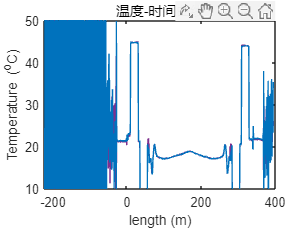

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');

% 202207Borehole [69.699,169.6,269.754]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=69.699 && DTS.LAF(k,1)<=169.6
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-69.699;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=169.6 && DTS.LAF(k,1)<=269.754
        q = q+1;
        Test1Process2.anti_depth(q,1) = 269.754-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);

clear k q

#### Chech the results

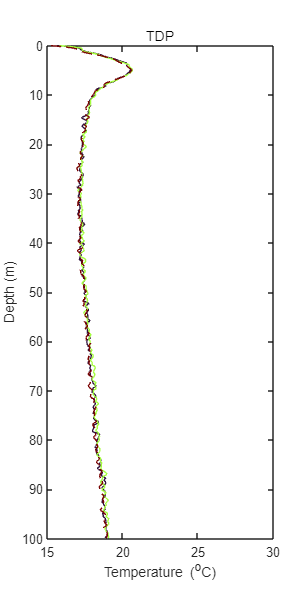

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,80),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);

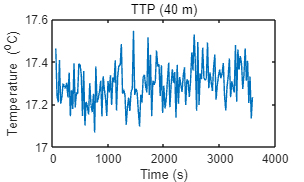

clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load jintan.mat jintan
jintan.bore1.depth20221123 = Test1Process2.depth;
jintan.bore1.temperature202211231850= mean(Test1Process2.temperature(:,1:end),2);
save jintan.mat jintan

#### 7 Save the processed data;

save data_jintan_01_20221125_process_202301100115.mat

#### 8 Next one

clear
clc